clear, close all

%Testing calculating the Jacobian for 4 sections






%Inputs
n = 4;
r = 5*2/pi/2;
%Find a desired pose
q_des = [4 5 6 5 4 5 6 6 7 7 4 5];
T_des = find_tip(q_des,r,n);
%Convert to an actual pose
des_pos = T_des(1:3,4); %Tip position
des_eul = rotm2eul(T_des(1:3,1:3))';  % returns [yaw, pitch, roll]
des_pose = [des_pos;des_eul];

des_pose = [-7 5 20 -1 1.5 -1]';
%des_pose = [1 1 17 0 0 0]'; %Test
gamma = .01;
Kp = 2;
q0 = [4 4 4 4 4 4 4 4 4 4 4 4]'; %Test lengths

num_cycles = 1000;
fake_t = linspace(0,10,num_cycles);
pose_new = zeros(num_cycles,6);
q_set = zeros(num_cycles,12);
new_q = q0;
max_delta = .01;
for i = 1:num_cycles
    q_set(i,:) = new_q;
    [deltaL,pose_new(i,:)] = find_deltaL(new_q,des_pose,gamma,Kp,r,n);
    for k = 1:length(deltaL)
        if abs(deltaL(k))>max_delta
            if deltaL(k) >0
                deltaL(k) = max_delta;
            else
                deltaL(k) = -max_delta;
            end
        end
    end
    for j = 1:length(deltaL)
        if (new_q(j)+deltaL(j))>= 8
            deltaL(j) = 0;
        elseif (new_q(j)+deltaL(j)) <= 4
            deltaL(j) = 0;
        end
    end
    new_q = new_q+deltaL;
end


des_pose

des_pose =    -7.0000
    5.0000
   20.0000
   -1.0000
    1.5000
   -1.0000


pose_new(num_cycles,:)'

ans =    -6.9361
    4.9972
   20.0083
   -1.0443
    1.5031
   -1.0416


q_set(num_cycles,:)

ans =     7.9240    6.2524    5.4986    7.6595    7.9966    7.3160    5.2472    6.5381    7.9023    4.0049    7.9868    7.6134


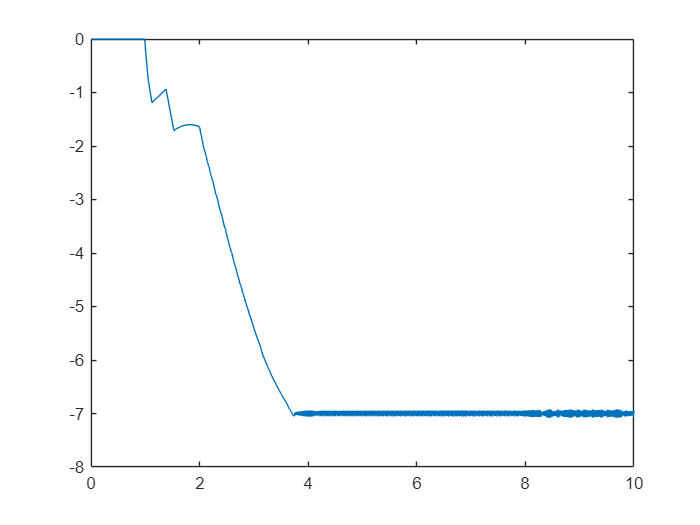

plot(fake_t,pose_new(:,1))

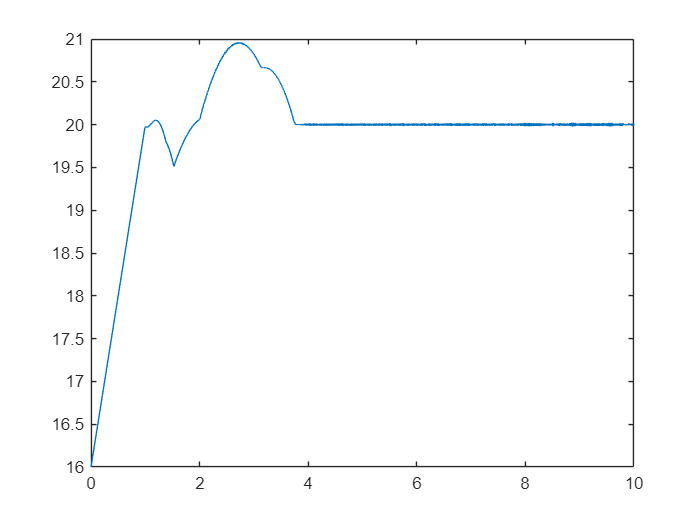

plot(fake_t,pose_new(:,3))

q_test = [4.01 4 4 4.01 4 4.01 4 4 4 4.01 4 4]';
J_test = calc_J(n,r,q_test);
delta_q = [.01 0 0 0 0 0 0 0 0 0 0 0]';


%This is really sad, but chatGPTs version works better than mine :(
function J_numeric = numerical_jacobian(q, r, n, epsilon)
%NUMERICAL_JACOBIAN Numerically compute the 6x(3n) Jacobian matrix
%   using finite differences on actuator lengths q.
%
% Inputs:
%   q        - actuator lengths vector (3n x 1)
%   r        - robot radius or relevant parameter
%   n        - number of segments
%   epsilon  - small perturbation value (optional, default 1e-6)
%
% Output:
%   J_numeric - numerical Jacobian matrix (6 x 3n)
%
% Pose is [position; rotation_vector] where rotation_vector is axis-angle

if nargin < 4
    epsilon = 1e-6;
end

m = length(q);      % number of actuator variables
J_numeric = zeros(6, m);

% Helper function to convert rotation matrix to rotation vector safely
    function rotvec = rotm2rotvec_safe(R)
        axang = rotm2axang(R);  % [axis(1:3), angle]
        angle = axang(4);
        if abs(angle) < 1e-5
            % Angle near zero → no rotation, set rotation vector to zero
            rotvec = zeros(3,1);
        else
            rotvec = axang(1:3)' * angle;
        end
    end

% Compute nominal pose
T0 = find_tip(q, r, n);
p0 = T0(1:3,4);
R0 = T0(1:3,1:3);
rotvec0 = rotm2rotvec_safe(R0);
pose0 = [p0; rotvec0];

% Compute finite difference for each actuator variable
for i = 1:m
    dq = zeros(m,1);
    dq(i) = epsilon;
    q_perturbed = q + dq;

    T1 = find_tip(q_perturbed, r, n);
    p1 = T1(1:3,4);
    R1 = T1(1:3,1:3);
    rotvec1 = rotm2rotvec_safe(R1);
    pose1 = [p1; rotvec1];

    % Numerical partial derivative
    J_numeric(:, i) = (pose1 - pose0) / epsilon;
end

% === Inject artificial rotation near singularities ===
lambda = 1e-4;  % small artificial gain
tol = 1e-5;     % tolerance for detecting singularity

for k = 1:n
    idx = (k-1)*3 + (1:3);  % Indices for segment k
    qk = q(idx);            % Lengths for segment k

    % Check if lengths are nearly equal (singular configuration)
    if max(qk) - min(qk) < tol
        % Inject structured rotation sensitivity
        J_numeric(4:6, idx) = J_numeric(4:6, idx) + lambda * ...
            [1 0 -1;
             0 1 -1;
            -1 1  0];
    end
end

end



%
function [deltaL,act_pose] = find_deltaL(q,des_pose,gamma,Kp,r,n)
    %J = calc_J(n,r,q);
    J = numerical_jacobian(q,r,n); %Numerical calculation, works somehow
    tip_T = find_tip(q,r,n);
    tip_T = real(tip_T);
    %Convert to an actual pose
    tip_pos = tip_T(1:3,4); %Tip position
    
    
    %tip_eul = rotm2eul(real(tip_T(1:3,1:3)))';  % returns [yaw, pitch, roll]
    %act_pose = [tip_pos;tip_eul];
    
    R_des = eul2rotm(des_pose(4:6)', 'ZYX');  % Assuming ZYX Euler input
    R_act = tip_T(1:3, 1:3);
    % Rotation error matrix
    R_err = R_des * R_act';  % NOTE: Not R_act * R_des'
    % Convert rotation error to rotation vector (axis * angle)
    % I don't really undersatand this part but its mroe stable than using
    % Euler angles
    axang = rotm2axang(real(R_err));  % [axis(1:3), angle]
    e_rot = axang(1:3)' * axang(4);  % rotation vector (3x1)

    % Full 6D error: [position_error; rotation_vector]
    pos_err = des_pose(1:3) - tip_pos;
    error = [pos_err; e_rot];
    % Output actual pose for logging
    act_eul = rotm2eul(real(R_act), 'ZYX')';
    act_pose = [tip_pos; act_eul];
    act_pose = real(act_pose);
    deltaL = (J'*J+gamma*eye(3*n))\(J'*(Kp*error));
end



%Finction that finds orientation of the end effector
function T_tot = find_tip(q,r,n)
    T_tot = eye(4);
    for i = 1:n %For each segment
        L_1 = q(1+3*(i-1));
        L_2 = q(2+3*(i-1));
        L_3 = q(3+3*(i-1));
        T_k = gen_transform(L_1,L_2,L_3,r);
        T_tot = T_tot*T_k;
    end

end


%Function that finds T_k from set of lengths and r
function T_k = gen_transform(L_k1,L_k2,L_k3,r)

    %Credit to https://doi.org/10.1038/s41467-024-54327-6 for the modeling
    %walkthrough
   
    %Might need to define phi_kj
    
    %Length matrix
    
    %Length of center
    L_ck = (L_k1+L_k2+L_k3)/3;
    %One angle
    beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
    %Another angle - see paper
    theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));
    %How to calculate the length of each actuator
    rho_k = beta_k/L_ck;
    %Logic for if straight
    if abs(rho_k) < 1e-6
        T_k = [1 0 0 0
               0 1 0 0
               0 0 1 L_ck
               0 0 0 1];
        return
    end
    R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
           (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
           -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];
    
    %This does not work when all lengths are equal
    P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
    T_k = [R_k P_k
            0 0 0 1];

    
    
end

%Function that takes a set of lengths q and outputs J
%This is currently broken. Not sure how to fix it
function J_calc = calc_J(n,r,q)
    
    phi_k = [0 2*pi/3 4*pi/3]'; %Actuator Pos
    
    R_tot = eye(3);
    
    
    J_LkQkl = cell(n,1);
    J_vkQkl = cell(n,1);
    J_wkQkl = cell(n,1);
    J_vkQk = cell(n,1);
    J_wkQk = cell(n,1);
    JLkQk = cell(n,1);
    JXk = cell(n,1);
    %Loop over all 4 sections
    for i = 1:n
        
        
        L_k1 = q(1+3*(i-1));
        L_k2 = q(2+3*(i-1));
        L_k3 = q(3+3*(i-1));
        

        if std([L_k1, L_k2, L_k3]) < 1e-6
            L_k2 = L_k2 + 1e-4;  % Break symmetry just enough to give curvature
        end

        L_ck = (L_k1+L_k2+L_k3)/3;
        %One angle
        beta_k = 2*sqrt(L_k1^2+L_k2^2+L_k3^2-L_k1*L_k2-L_k1*L_k3-L_k2*L_k3)/(3*r);
        %Another angle - see paper
        theta_k = atan2(3*(L_k2-L_k3),sqrt(3)*(L_k2+L_k3-2*L_k1));
        rho_k = beta_k/L_ck;
        

        %Gonna need to calculate and store R0_k-1 and Pk-1k
        R_k = [cos(beta_k)*cos(theta_k)^2 + sin(theta_k)^2 (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)*sin(beta_k)
               (-1+cos(beta_k))*cos(theta_k)*sin(theta_k) cos(theta_k)^2+cos(beta_k)*(sin(theta_k))^2 sin(theta_k)*sin(beta_k)
               -cos(theta_k)*sin(beta_k) -sin(beta_k)*sin(theta_k) cos(beta_k)];
        
        R0_k1 = R_tot; %0 to k-1
        %This does not work when all lengths are equal
        
    
        R_tot = R_tot*R_k;
        
        %Need logic for if zero curvature
        if rho_k == 0
            J_LkQkl{i} = [1 0 0;
                          1 0 0;
                          1 0 0];

            J_vkQkl{i} = [0 0 0;
                          0 0 0;
                          1/3 1/3 1/3]; 
        
            J_wkQkl{i} = zeros(3,3);
            
            P_k = [0 0 L_ck]'; %Quick fix
        else
            J_LkQkl{i} = [1 r*beta_k*sin(theta_k-phi_k(1)) -r*cos(phi_k(1)-theta_k)
                         1 r*beta_k*sin(theta_k-phi_k(2)) -r*cos(phi_k(2)-theta_k)
                         1 r*beta_k*sin(theta_k-phi_k(3)) -r*cos(phi_k(3)-theta_k)];
            
            %This one is sus
            J_vkQkl{i} = [(1-cos(beta_k))*cos(theta_k)/beta_k (-1+cos(beta_k))*sin(theta_k)/rho_k cos(theta_k)*(-1+cos(beta_k)+beta_k*sin(beta_k))/(rho_k*beta_k)
                       (1-cos(beta_k))*sin(theta_k)/beta_k (-1+cos(beta_k))*cos(theta_k)/rho_k sin(theta_k)*(-1+cos(beta_k)+beta_k*sin(beta_k))/(rho_k*beta_k)
                       sin(beta_k)/beta_k 0 (-sin(beta_k)+beta_k*cos(beta_k))/(rho_k*beta_k)];
            
            J_wkQkl{i} = [0 -cos(theta_k)*sin(beta_k) -sin(theta_k)
                       0 -sin(theta_k)*sin(beta_k) cos(theta_k)
                       0 1-cos(beta_k) 0];

            P_k = 1/rho_k*[(1-cos(beta_k))*cos(theta_k) (1-cos(beta_k))*sin(theta_k) sin(beta_k)]';
        end
        %Next calc JLkQk
        if i == 1
            
            J_vkQk{i} = J_vkQkl{i};
            J_wkQk{i} = J_wkQkl{i};
    
            JLkQk{i} = J_LkQkl{i};
        else
            
            
            %Lets check the size, this is 3(i-1)x3
            %This is needed and need to convert it to hat for some reason
            p_global = R0_k1 * P_k;
            p_hat = [      0        -p_global(3)  p_global(2);
                       p_global(3)       0       -p_global(1);
                     -p_global(2)  p_global(1)        0      ]; % skew-symmetric matrix
    
    
            %This weird multiplication term needs to be 3(i-1)x3
            J_vkQk{i} = [(J_vkQk{i-1}-p_hat*J_wkQk{i-1}), (R0_k1*J_vkQkl{i})];
    
            J_wkQk{i} = [J_wkQk{i-1} (R0_k1*J_wkQkl{i})];
            
            %This is really weird but I see no other way to get the bottom left
            %term, and the paper does not say
            %part1 = JLkQk{i-1}(1:3,:); 
           
            
            %part2 = -p_hat*J_wkQk{i-1};
    
            %bottom_left = part1 + part2;
            bottom_left = J_vkQk{i-1} - p_hat * J_wkQk{i-1};
            JLkQk{i} = [JLkQk{i-1} zeros(3*(i-1),3)
                        bottom_left J_LkQkl{i}];
            
    
        end
        
        JXk{i} = [J_vkQk{i}' J_wkQk{i}']';
        
    
    end
    
    %J_calc = JXk{n}/JLkQk{n};
    J_calc = JXk{n} * inv(JLkQk{n});
end
%Ok now we have calculated J, lets try the optimization



